# Expand Example 6.5:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Design a 3rd-order Chebyshev type-II analog lowpass filter with stopband edge frequency $\omega_{2}=3$ rad/s and parameter $\varepsilon=0.2$.

% Set design parameters
epsilon = 0.2;
omg2 = 3;  % Critical frqequency
N = 3;     % Filter order
% Create a vector of indices for the Chebyshev filter poles.
k = [0:2*N-1]';
% Compute parameters
alpha_k = (2*k+1)*pi/(2*N)

alpha_k =     0.5236
    1.5708
    2.6180
    3.6652
    4.7124
    5.7596


beta = asinh(1/epsilon)/N

beta = 0.7708

% Compute poles of H(s)H(-s)
disp('Poles of the filter:');

Poles of the filter:


pk = j*omg2./(cos(alpha_k)*cosh(beta)-j*sin(alpha_k)*sinh(beta))

pk =   -0.8659 + 2.3165i
  -3.5317 + 0.0000i
  -0.8659 - 2.3165i
   0.8659 - 2.3165i
   3.5317 - 0.0000i
   0.8659 + 2.3165i


% Find zeros of H(s)
k = [1:(N-1)/2]';
zk = j*omg2./cos((2*k-1)*pi/(2*N));
disp('Zeros of the filter;');

Zeros of the filter;


zk = [zk;-zk]

zk =    0.0000 + 3.4641i
   0.0000 - 3.4641i


% Compute denominator coefficients
disp('Denominator coefficients:');

Denominator coefficients:


den = real(conv([1,-pk(1)],conv([1,-pk(2)],[1,-pk(3)])))

den =     1.0000    5.2635   12.2320   21.6000


% Compute numerator coefficients
num = real(conv([1,-zk(1)],[1,-zk(2)]));
% Compute the frequency response
disp('Numerator coefficients:');

Numerator coefficients:


num = num*den(4)/num(3)  % Adjust for unit gain at dc

num =     1.8000         0   21.6000


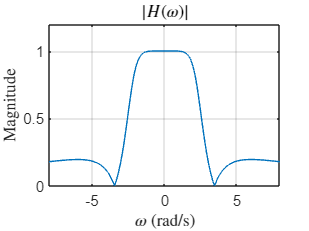

omg = [-8:0.01:8];
H = freqs(num,den,omg);
% Graph the magnitude and the phase of the frequency response
plot(omg,abs(H)); grid;
set(0,'defaultTextInterpreter','latex');
axis([-8,8,0,1.2]);
xlabel('$\omega$ (rad/s)');
ylabel('Magnitude');
title('$|H(\omega)|$');

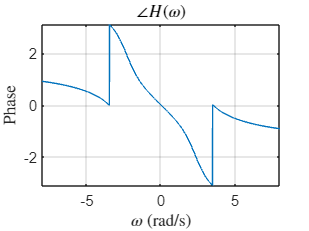

plot(omg,angle(H)); grid;
axis([-8,8,-pi,pi]);
xlabel('$\omega$ (rad/s)');
ylabel('Phase');
title('$\angle H(\omega)$');

set(0,'defaultTextInterpreter','tex');